## Test Augmented IVP Solver

% https://home.cs.colorado.edu/~lizb/chaos/variational-notes.pdf
clear
clc
close

format longg

a = 0.398;
b = 2;
c = 4;


odefun = @(t, x) [ - x(2) - x(3);
                    x(1) + a * x(2);
                    b + x(3) * (x(1) - c)];

jacobianfun = @(t, x) [0 -1 -1;
                1 a 0;
                x(3) 0 x(1) - c]; 

incond = [0 1 2];
tau = 5e-2;
tspan = [0 5];

% Coefficients of the classical Runge—Kutta method of the 4th order.

c_vector = [0 1/2 1/2 1] .'; 

A_matrix = [0 0 0 0; 
            1/2 0 0 0; 
            0 1/2 0 0; 
            0 0 1 0];

b_vector = [1/6 1/3 1/3 1/6] .';

[~, xsol] = augmentedODEExplicitGeneral(c_vector, A_matrix, b_vector, odefun, jacobianfun, tspan, tau, incond);

test_result = xsol(end, :) .'

test_result =           2.67560445595244
        0.0456389470748418
          1.61549958197901
          1.13289032328128
         -1.68836133648388
         0.208619664213827
          1.52002431902738
        -0.524986437342869
          1.60686536918438
        -0.188761366052454


## Lyapunov Exponents of The Rössler Attractor

clear
close
clc

a = 0.2;
b = 0.2;
c = 5.7;

odefun = @(t, x) [ - x(2) - x(3);
                    x(1) + a * x(2);
                    b + x(3) * (x(1) - c)];

jacobianfun = @(t, x) [0 -1 -1;
                1 a 0;
                x(3) 0 x(1) - c]; 

incond = [1 1 1];
tau = 5e-2;
tspan = [0 1e5];

% Coefficients of the classical Runge—Kutta method of the 4th order.

c_vector = [0 1/2 1/2 1] .'; 

A_matrix = [0 0 0 0; 
            1/2 0 0 0; 
            0 1/2 0 0; 
            0 0 1 0];

b_vector = [1/6 1/3 1/3 1/6] .';

[t, xsol, lyap_exp] = odeExplicitGeneralLE(c_vector, A_matrix, b_vector, odefun, jacobianfun , tspan, tau, incond);

D_KY ≈ 2.01337



LEs = lyap_exp(end, :) .'

LEs =         0.0720076344550246
      9.87345461988459e-06
         -5.38765357716368


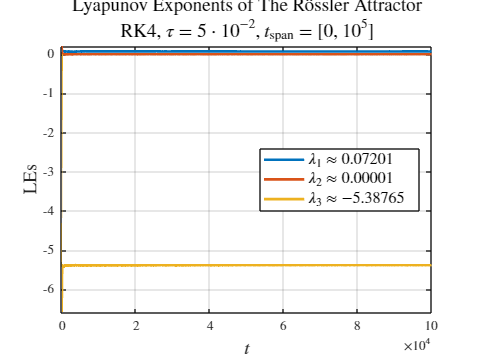

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

close
figure

plot(t, lyap_exp, "LineWidth", 2)
grid on;
box on;
axis tight
xlabel('$t$', 'FontSize', 14);
ylabel('LEs', 'FontSize', 14);
title(['Lyapunov Exponents of The R\"ossler Attractor', "RK4, $\tau = 5 \cdot 10^{-2}, ~t_{\mathrm{span}} = [0,~ 10^{5}]$"], 'FontSize', 14);
legend(compose("$\\lambda_{%d} \\approx %.5f$", (1:3) .', LEs), 'FontSize', 12, 'Location', 'best')

% exportgraphics(gcf, "images\LEs_plot.png", "Resolution", 900)

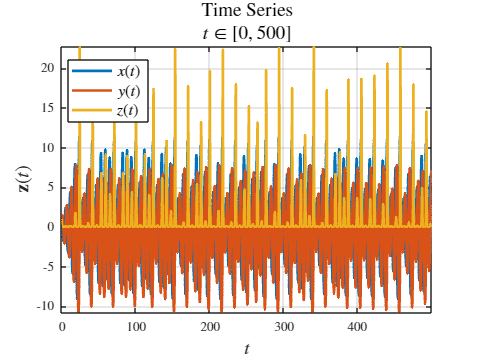

close
figure

plot(t(1:1e4), xsol(1:1e4, 1:3), "LineWidth", 2)
grid on;
box on;
axis tight
xlabel('$t$', 'FontSize', 14);
ylabel('$\mathbf{z}(t)$', 'FontSize', 14);
title(["Time Series" "$t\in[0,~ 500]$"], 'FontSize', 14)
legend(["$x(t)$" "$y(t)$" "$z(t)$"], 'FontSize', 12, 'Location', 'best')

% exportgraphics(gcf, "images\time_series.png", "Resolution", 900)

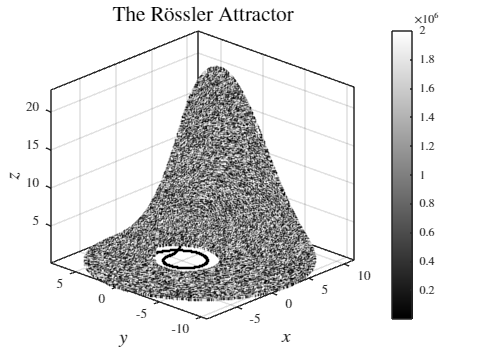

close
figure
scatter3(xsol(:, 1), xsol(:, 2), xsol(:, 3), 4, 1:length(xsol(:, 1)), 'filled');
view([-46.8 25.2])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The R\"ossler Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images\The_Rossler_Attractor.png", "Resolution", 900)